Initialization

The main simulation paramters for the measured double-directional data is defined here

% Root folder containing double-directional data for 234 GHz and 318 GHz
dataRoot = 'C:\Users\nlafir23\OneDrive - University of Oulu and Oamk\Desktop\Data_MPC';

% Measured frequency bands 234 or 318 (GHz).
freqBand = 234;      

% Measurement scenario / environment.
%   'fablab'   - FabLab measurement campaign
%   'saalasti' - Saalasti hall measurements
%   'storage'  - Storage 
scenario = 'saalasti';          

% Enable/Disable visualization
visualizeAntenna = 1;           % 1 = plot Tx/Rx antenna patterns and array factor
visualizeChModel = 1;           % 1 = plot PDP and CFR for selected links
visualizeLayout  = 0;           % we have no scatterer positions

% Channel model type:
% 'snapshot' = single time snapshot (no time evolution of the channel).
par.modelType      = 'snapshot';      

% Antenna types at Tx and Rx:
%   'single3GPP' - single directional element with 3GPP radiation pattern
%   'URA'        - uniform rectangular array
%   'UCA'        - uniform circular array
par.tx.antennaType = 'UCA';            
par.rx.antennaType = 'UCA';            

par.fc   = freqBand * 1e9;     % center frequency [Hz]
par.BW   = 4e9;                % bandwidth [Hz]
par.linkSet = [];              % initizalization

Load the data for the scenario 

% Load the double-directional multipath component (MPC) data
% for the selected frequency band and measurement scenario.
% The helper function 'gen_pathDD_MPC.m' must be available 
% in the current MATLAB working directory.
% 
% Output:
%   pathData - cell array containing one entry per Tx–Rx link.
%              Each entry includes measured parameters such as:
%                 • Npaths       - number of detected MPCs
%                 • Tx/Rx angles - azimuth and elevation of departure/arrival
%                 • delays, powers, and possibly link distance
%                 • TxCoord, RxCoord - coordinates 

pathData = gen_pathDD_MPC(freqBand, scenario, dataRoot); 

Using file: C:\Users\nlafir23\OneDrive - University of Oulu and Oamk\Desktop\Data_MPC\234GHz\Multipath_234GHz_Saalasti_Hall_HR145.mat
Using variable "RTData"


Visualize the data summary

% Total number of measured Tx–Rx links
Nlinks  = numel(pathData);

Npaths  = zeros(Nlinks,1);
linkDist = zeros(Nlinks,1);

for iL = 1:Nlinks
    if ~isnan(pathData{iL}.Npaths)
        Npaths(iL)   = pathData{iL}.Npaths;
        % if you stored link distance in your .mat:
        if isfield(pathData{iL},'linkDist')
            linkDist(iL) = pathData{iL}.linkDist;
        else
            % compute from Tx/Rx coords if you want:
            Tx = pathData{iL}.TxCoord(:);
            Rx = pathData{iL}.RxCoord(:);
            linkDist(iL) = norm(Tx-Rx);
        end
    else
        Npaths(iL) = 0;
        linkDist(iL) = NaN;
    end
end

% Summary table of link index, number of paths, and distance

Tsummary = table((1:Nlinks)', Npaths, linkDist, ...
    'VariableNames', {'LinkIdx','Npaths','LinkDist_m'});
disp(Tsummary);

    LinkIdx    Npaths    LinkDist_m
    _______    ______    __________

       1         1          0.401  
       2         2         3.0366  
       3         2         9.1101  
       4         3         7.1982  
       5         3         6.2913  
       6         3          6.669  
       7         3         8.2146  
       8         2         14.727  
       9         3         12.776  
      10         3         11.874  
      11         4         12.306  
      12         2         20.962  
      13         2         19.585  
      14         3         18.162  
      15         2         17.139  
      16         2         16.621  
      17         2         25.608  
      18         1         22.632  
      19         3        0.40012  
      20         2         9.1101  
      21         4         7.2196  
      22         1         6.2414  
      23         2         6.8159



if isempty(par.linkSet)
    par.linkSet = 1:numel(pathData);   % use all links by default
end

SD     = 2;                   % oversampling factor (unused in snapshot)
SoL    = 299792458;           % speed of light [m/s]
lambda = SoL/par.fc;          % wavelength [m]
switch par.modelType
    case 'snapshot'
        par.Ntime = 1;
    otherwise
        error('This main script supports only snapshot modelType.');
end


Define Tx antenna beam

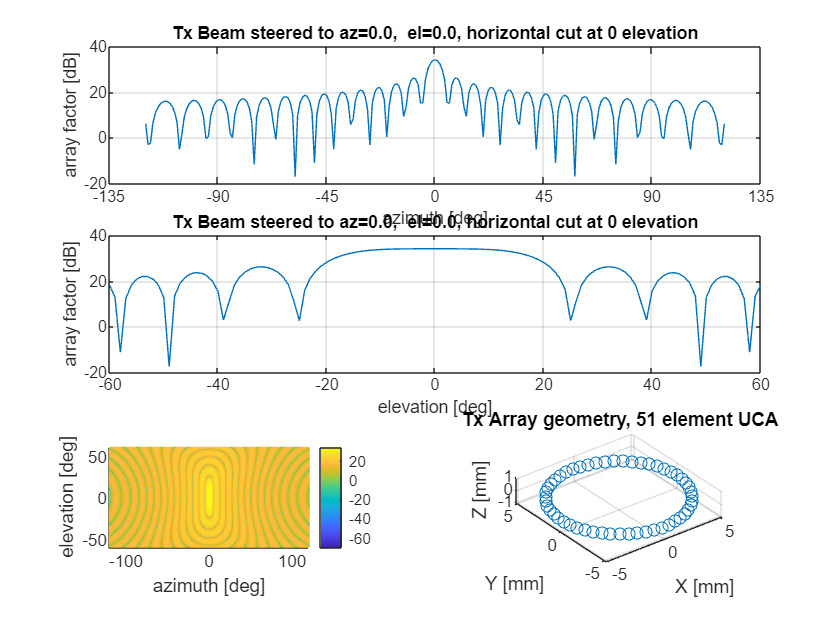

%% Define Tx beam shape / antenna array %%%%%%%%%%%%%%%%%%%%
% Note: omni-directional elements are assumed in ULA and UCA
switch par.tx.antennaType
    case 'single3GPP'
        Nant = 1;           % Number of antenna elements (must be = 1)
        % 3GPP radiation power pattern (defined in TR 38.901 Table 7.3-1)
        az = -179:180;      % azimuth angles for beam sampling [deg] (Keep 1 deg increment!)
        el = -90:90;        % elevation angles for beam sampling [deg] (Keep 1 deg increment!)
        theta_3dB = 20;     % Set here the vertical HPBW [deg]
        phi_3dB = 10;       % Set here the horizontal HPBW [deg]
        Amax = 30;          % max attenuation [dB]
        G_Emax = 8;  % Maximum directional gain of an antenna element [dBi]
        Aver_dB = -min(12*(el/theta_3dB).^2,Amax);  % V cut
        Ahor_dB = -min(12*(az/phi_3dB).^2,Amax);    % H cut
        % Az & El gain pattern matrix (Nelev x Nazim)
        A_dB = G_Emax-min(-(repmat(Ahor_dB,length(el),1)...
                           +repmat(Aver_dB',1,length(az))),Amax);
        
        % Beam orientation: 'max' to max power AoA = adaptive OR fixed AoA&EoA angle [deg]
%         orientA = [23,-15];  % beam orientation {'max' OR [azimuth,elevation] in deg}
        orientA = 'max';    % beam orientation {'max' OR [azimuth,elevation] in deg}

        if ~strcmpi(orientA,'max')
            A_dB = circshift(A_dB,[orientA(2) orientA(1)]);
        end
        
        if visualizeAntenna
            figure(1)
            subplot(3,1,1)
            plot(az,G_Emax+Ahor_dB), grid on
            xlabel('azimuth [deg]'),ylabel('radiation power pattern [dB]')
            title(sprintf('Tx Single 3GPP beam, horizontal cut, HPBW = %.1f deg',phi_3dB))
            subplot(3,1,2)
            plot(el,G_Emax+Aver_dB), grid on
            xlabel('elevation [deg]'),ylabel('radiation power pattern [dB]')
            title(sprintf('Tx Single 3GPP beam, vertical cut HPBW = %.1f deg',theta_3dB))
            subplot(3,1,3)
            surf(az,el,A_dB, 'EdgeColor','flat'), axis equal, view(2)
            xlabel('azimuth [deg]'),ylabel('elevation [deg]'),zlabel('gain [dB]')
            colorbar
        end
        % Note! 3gpp specifies -180:180, meas data is 0:360 -> shift
        A_dB = circshift(A_dB,[0 -180]);
        az = 1:360;          % azimuth grid now 1..360 deg

        % store pattern & grids in tx struct
        tx.A_dB   = A_dB;    % gain matrix (el x az)
        tx.azPat  = az;      % azimuth axis for pattern
        tx.elPat  = el;      % elevation axis for pattern
        tx.orientA = orientA;
        tx.acoord  = [0 0 0];    % dummy antenna coordinates

        
    case 'URA'
        Nrow = 4;          % Number of URA antenna element rows
        Ncol = 8;          % Number of ULA antenna element columns
        Nant = Nrow*Ncol;  % Number of URA antenna elements
        rowSpacing = 0.5;  % vertical element spacing [wavelength]
        colSpacing = 0.5;  % horizontal element spacing [wavelength]
        % Beam orientation: 'max' to max power AoA = adaptive OR fixed AoA&EoA angle [deg]
%         orientA = [23,-15];  % beam orientation {'max' OR azimuth,elevation in deg}
        orientA = 'max';    % beam orientation {'max' OR azimuth,elevation in deg}
                
        xa = zeros(1,Nant);     % array x coordinates [m]
        ytmp = 0:colSpacing:colSpacing*(Ncol-1); 
        ytmp = (ytmp - max(ytmp)/2);
        ztmp = 0:rowSpacing:rowSpacing*(Nrow-1); 
        ztmp = (ztmp - max(ztmp)/2);
        [ya,za] = meshgrid(ytmp,ztmp);
        ya = ya(:)'*lambda;   % array y coordinates [m]
        za = za(:)'*lambda;   % array z coordinates [m]
        acoord = [xa', ya', za'];  % URA coordinates  [m]
        
        if ~strcmpi(orientA,'max')
            rotEle = roty(orientA(2));  % matrix for elvation rotation
            rotAzi = rotz(orientA(1));  % matrix for azimuth rotation
            tmp = rotEle*acoord';       % y rotation first
            tmp = rotAzi*tmp;           % then z rotation
            acoord = tmp';
        end
        tx.acoord = acoord;
        tx.orientA = orientA;
       
    case 'UCA'
        % UCA, since azimuth only data, no bore sight definition needed
        aper = 8;   % horizontal UCA aperture = diameter in [wavelength]
        Nant = ceil(aper*pi*2);  % Number of elements with <=lambda/2 spacing
        [xa,ya] = pol2cart(linspace(0,2*pi,Nant+1),aper/2*lambda);
        acoord = [xa', ya', zeros(length(xa),1)];     % UCA coordinates [m]
        acoord(end,:) = [];      % Remove the redundant element
        tx.acoord = acoord;
        tx.orientA = 'uca';
        
    otherwise
        error('Check the par.antennaType parameter value!')
end

tx.Nant = Nant;

if visualizeAntenna & sum(strcmpi(par.tx.antennaType,{'URA','UCA'})) 
    figure(1)
    subplot(3,2,5)
    % Beam scanning angles in azimuth & elevation [deg]
    [azq,elq] = meshgrid([-120:1:120],[-60:1:60]);   % az,el range  
    betaq = [cosd(azq(:)).*cosd(elq(:)),...
             sind(azq(:)).*cosd(elq(:)),...
             sind(elq(:))]*2*pi/lambda; % wave vectors from scan angles [m]
    % Determine intended steering vector (=digital BF weight vector)
    angAzSt = 0;         % Azimuth direction of the intended steering vector [deg]
    angElSt = 0;         % Elevation direction of the intended steering vector [deg]
    gamma = -[cosd(angAzSt).*cosd(angElSt), sind(angAzSt).*cosd(angElSt), sind(angElSt)]*2*pi/lambda;    % wave vector to direction of angSt
    vecSt = exp(1j*gamma*acoord'); % Steering vector to direction of angSt (complex)
    af = sum(exp(1j*(betaq*acoord' + repmat(angle(vecSt),length(betaq),1)) ),2);    % Array factor
    afMat = reshape(af,size(azq,1),size(azq,2));    % Array factor matrix (ele x azi)
    surf(azq,elq,20*log10(abs(afMat)),'EdgeColor','flat'), 
    axis equal, view(2), colorbar
    xlabel('azimuth [deg]'),ylabel('elevation [deg]'),zlabel('array factor [dB]')
    
    subplot(3,2,[1 2])
    ind = find(elq==0);
    plot(azq(ind),20*log10(abs(afMat(ind)))), grid on
    set(gca,'XTick',[-135:45:135]), xlim([-135 135])
    xlabel('azimuth [deg]'),ylabel('array factor [dB]')
    title(sprintf('Tx Beam steered to az=%.1f,  el=%.1f, horizontal cut at 0 elevation',angAzSt,angElSt))
    
    subplot(3,2,[3 4])
    ind = find(azq==0);
    plot(elq(ind),20*log10(abs(afMat(ind)))), grid on
    xlabel('elevation [deg]'),ylabel('array factor [dB]')
    title(sprintf('Tx Beam steered to az=%.1f,  el=%.1f, horizontal cut at 0 elevation',angAzSt,angElSt))
    
    subplot(3,2,6)
    plot3(tx.acoord(:,1)*1E3,tx.acoord(:,2)*1E3,tx.acoord(:,3)*1E3,'o')
    grid on, axis square equal
    xlabel('X [mm]'),ylabel('Y [mm]'),zlabel('Z [mm]')
    title(sprintf('Tx Array geometry, %d element %s',Nant,par.tx.antennaType))
end

Define Rx beam

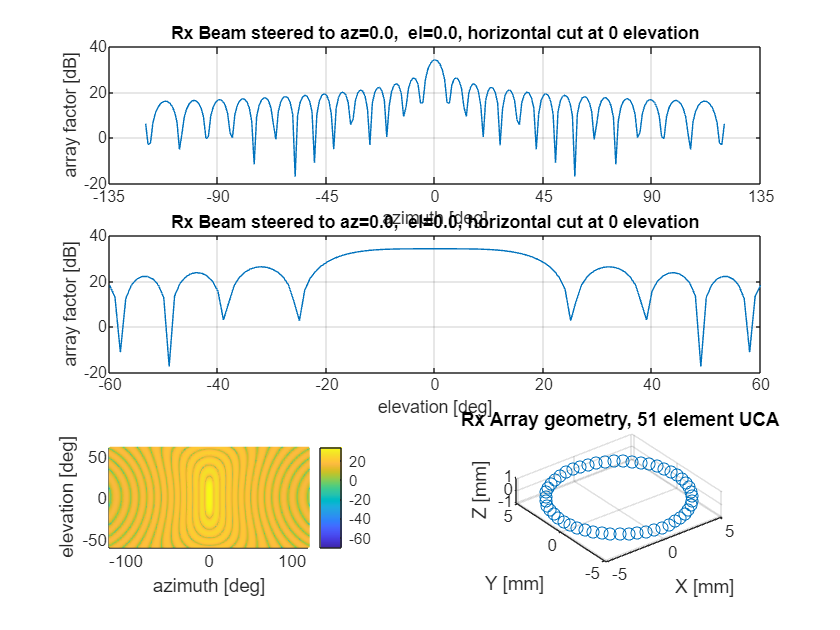

%% Define Rx beam shape / antenna array %%%%%%%%%%%%%%%%%%%%
% Note: omni-directional elements are assumed in ULA and UCA
switch par.rx.antennaType
    case 'single3GPP'
        Nant = 1;           % Number of antenna elements
        % 3GPP radiation power pattern (defined in TR 38.901 Table 7.3-1)
        az = -179:180;      % azimuth angles for beam sampling [deg] (Keep 1 deg increment!)
        el = -90:90;        % elevation angles for beam sampling [deg] (Keep 1 deg increment!)
        theta_3dB = 20;     % Set here the vertical HPBW [deg]
        phi_3dB = 10;       % Set here the horizontal HPBW [deg]
        Amax = 30;          % max attenuation [dB]
        G_Emax = 8;  % Maximum directional gain of an antenna element [dBi]
        Aver_dB = -min(12*(el/theta_3dB).^2,Amax);  % V cut
        Ahor_dB = -min(12*(az/phi_3dB).^2,Amax);    % H cut
        % Az & El gain pattern matrix (Nelev x Nazim)
        A_dB = G_Emax-min(-(repmat(Ahor_dB,length(el),1)...
                           +repmat(Aver_dB',1,length(az))),Amax);
        
        % Beam orientation: 'max' to max power AoA = adaptive OR fixed AoA&EoA angle [deg]
%         orientA = [23,-15];  % beam orientation {'max' OR [azimuth,elevation] in deg}
        orientA = 'max';    % beam orientation {'max' OR [azimuth,elevation] in deg}

        if ~strcmpi(orientA,'max')
            A_dB = circshift(A_dB,[orientA(2) orientA(1)]);
        end
        
        if visualizeAntenna
            figure(3)
            subplot(3,1,1)
            plot(az,G_Emax+Ahor_dB), grid on
%             plot(az+orientA,G_Emax+Ahor_dB), grid on
            xlabel('azimuth [deg]'),ylabel('radiation power pattern [dB]')
            title(sprintf('Rx Single 3GPP beam, horizontal cut, HPBW = %.1f deg',phi_3dB))
            subplot(3,1,2)
            plot(el,G_Emax+Aver_dB), grid on
%             plot(el+orientE,G_Emax+Aver_dB), grid on
            xlabel('elevation [deg]'),ylabel('radiation power pattern [dB]')
            title(sprintf('Rx Single 3GPP beam, vertical cut HPBW = %.1f deg',theta_3dB))
            subplot(3,1,3)
            surf(az,el,A_dB, 'EdgeColor','flat'), axis equal, view(2)
            xlabel('azimuth [deg]'),ylabel('elevation [deg]'),zlabel('gain [dB]')
            colorbar
        end
        % Note! 3gpp specifies -180:180, meas data is 0:360 -> shift
        A_dB = circshift(A_dB,[0 -180]);
        az = 1:360;

        % store pattern & grids in rx struct
        rx.A_dB   = A_dB;
        rx.azPat  = az;
        rx.elPat  = el;
        rx.orientA = orientA;
        rx.acoord  = [0 0 0];    % dummy antenna coordinates

        
    case 'URA'
        Nrow = 2;          % Number of URA antenna element rows
        Ncol = 3;          % Number of ULA antenna element columns
        Nant = Nrow*Ncol;  % Number of URA antenna elements
        rowSpacing = 0.5;  % vertical element spacing [wavelength]
        colSpacing = 0.5;  % horizontal element spacing [wavelength]
        % Beam orientation: 'max' to max power AoA = adaptive OR fixed AoA&EoA angle [deg]
%         orientA = [23,-15];  % beam orientation {'max' OR azimuth,elevation in deg}
        orientA = 'max';    % beam orientation {'max' OR azimuth,elevation in deg}
                
        xa = zeros(1,Nant);     % array x coordinates [m]
        ytmp = 0:colSpacing:colSpacing*(Ncol-1); 
        ytmp = (ytmp - max(ytmp)/2);
        ztmp = 0:rowSpacing:rowSpacing*(Nrow-1); 
        ztmp = (ztmp - max(ztmp)/2);
        [ya,za] = meshgrid(ytmp,ztmp);
        ya = ya(:)'*lambda;   % array y coordinates [m]
        za = za(:)'*lambda;   % array z coordinates [m]
        acoord = [xa', ya', za'];  % URA coordinates  [m]
        
        if ~strcmpi(orientA,'max')
            rotEle = roty(orientA(2));  % matrix for elvation rotation
            rotAzi = rotz(orientA(1));  % matrix for azimuth rotation
            tmp = rotEle*acoord';       % y rotation first
            tmp = rotAzi*tmp;           % then z rotation
            acoord = tmp';
        end
        rx.acoord = acoord;
        rx.orientA = orientA;
       
    case 'UCA'
        % UCA, since azimuth only data, no bore sight definition needed
        aper = 8;   % horizontal UCA aperture = diameter in [wavelength]
        Nant = ceil(aper*pi*2);  % Number of elements with <=lambda/2 spacing
        [xa,ya] = pol2cart(linspace(0,2*pi,Nant+1),aper/2*lambda);
        acoord = [xa', ya', zeros(length(xa),1)];     % UCA coordinates [m]
        acoord(end,:) = [];      % Remove the redundant element
        rx.acoord = acoord;
        rx.orientA = 'uca';
        
    otherwise
        error('Check the par.antennaType parameter value!')
end
rx.Nant = Nant;

if visualizeAntenna & sum(strcmpi(par.rx.antennaType,{'URA','UCA'})) 
    figure(2)
    subplot(3,2,5)
    % Beam scanning angles in azimuth & elevation [deg]
    [azq,elq] = meshgrid([-120:1:120],[-60:1:60]);   % az,el range  
    betaq = [cosd(azq(:)).*cosd(elq(:)),...
             sind(azq(:)).*cosd(elq(:)),...
             sind(elq(:))]*2*pi/lambda; % wave vectors from scan angles [m]
    % Determine intended steering vector (=digital BF weight vector)
    angAzSt = 0;         % Azimuth direction of the intended steering vector [deg]
    angElSt = 0;         % Elevation direction of the intended steering vector [deg]
    gamma = -[cosd(angAzSt).*cosd(angElSt), sind(angAzSt).*cosd(angElSt), sind(angElSt)]*2*pi/lambda;    % wave vector to direction of angSt
    vecSt = exp(1j*gamma*acoord'); % Steering vector to direction of angSt (complex)
    af = sum(exp(1j*(betaq*acoord' + repmat(angle(vecSt),length(betaq),1)) ),2);    % Array factor
    afMat = reshape(af,size(azq,1),size(azq,2));    % Array factor matrix (ele x azi)
    surf(azq,elq,20*log10(abs(afMat)),'EdgeColor','flat'), 
    axis equal, view(2), colorbar
    xlabel('azimuth [deg]'),ylabel('elevation [deg]'),zlabel('array factor [dB]')
    
    subplot(3,2,[1 2])
    ind = find(elq==0);
    plot(azq(ind),20*log10(abs(afMat(ind)))), grid on
    set(gca,'XTick',[-135:45:135]), xlim([-135 135])
    xlabel('azimuth [deg]'),ylabel('array factor [dB]')
    title(sprintf('Rx Beam steered to az=%.1f,  el=%.1f, horizontal cut at 0 elevation',angAzSt,angElSt))
    
    subplot(3,2,[3 4])
    ind = find(azq==0);
    plot(elq(ind),20*log10(abs(afMat(ind)))), grid on
    xlabel('elevation [deg]'),ylabel('array factor [dB]')
    title(sprintf('Rx Beam steered to az=%.1f,  el=%.1f, horizontal cut at 0 elevation',angAzSt,angElSt))   
    
    subplot(3,2,6)
    plot3(rx.acoord(:,1)*1E3,rx.acoord(:,2)*1E3,rx.acoord(:,3)*1E3,'o')
    grid on, axis square equal
    xlabel('X [mm]'),ylabel('Y [mm]'),zlabel('Z [mm]')
    title(sprintf('Rx Array geometry, %d element %s',Nant,par.rx.antennaType))
end

Generate CIR

% Outage links (where Npaths is NaN in the measurement data)
OutageIdx = cellfun(@(x) isnan(x.Npaths), pathData(par.linkSet));
par.linkSet = par.linkSet(~OutageIdx);
Nlink = length(par.linkSet);

% Determine maximum number of taps
tmpTaps = zeros(1, Nlink);
for i_link = 1:Nlink
    tmpTaps(i_link) = pathData{par.linkSet(i_link)}.Npaths;
end
maxTap = max(tmpTaps);

CIR   = zeros(Nlink, rx.Nant, tx.Nant, maxTap, par.Ntime);
Delay = zeros(Nlink, maxTap, par.Ntime);

orientTx = zeros(Nlink, 2);
orientRx = zeros(Nlink, 2);

for i_link = 1:Nlink
    pd   = pathData{par.linkSet(i_link)};
    powe = pd.specPaths_UsedDyR.power;   % [dB]
    dela = pd.specPaths_UsedDyR.delay;   % [s]

    % ----- ANGLES FROM pathData (using your new convention) -----
    % TxTheta, RxTheta : azimuth [deg]
    % TxPhi,   RxPhi   : elevation [deg]

    aod = pd.specPaths_UsedDyR.TxTheta;   % AoD azimuth
    aoa = pd.specPaths_UsedDyR.RxTheta;   % AoA azimuth

    eod = pd.specPaths_UsedDyR.TxPhi;     % Tx elevation
    eoa = pd.specPaths_UsedDyR.RxPhi;     % Rx elevation

    Npath = pd.Npaths;
    Delay(i_link,1:Npath) = dela(:)';

    % random phase per path
    phasor = exp(1j * 2*pi * rand(1, Npath));

    % Orientation towards strongest path (elev, azim)
    [~, idxMax] = max(powe);
    orientTx(i_link,:) = round([eod(idxMax), aod(idxMax)]);  % [elev, azim]
    orientRx(i_link,:) = round([eoa(idxMax), aoa(idxMax)]);




    Npath = pd.Npaths;

    Delay(i_link,1:Npath) = dela(:)';

    % random phase per path
    phasor = exp(1j * 2*pi * rand(1, Npath));

    % Orientation towards strongest path (elev, azim)
    [~, idxMax] = max(powe);
    orientTx(i_link,:) = round([eod(idxMax), aod(idxMax)]);
    orientRx(i_link,:) = round([eoa(idxMax), aoa(idxMax)]);

    % ---------- TX antenna gains ----------
    if strcmpi(par.tx.antennaType, 'single3GPP')
        if strcmpi(tx.orientA, 'max')
            A_dB_rot = circshift(tx.A_dB, orientTx(i_link,:));
        else
            A_dB_rot = tx.A_dB;
        end
        antGain_dB = interp2(tx.azPat, tx.elPat, A_dB_rot, aod, eod);
        tx.antGain = 10.^(antGain_dB/20);
        tx.rotAcoord(:,:,i_link) = tx.acoord;
    else
        if strcmpi(tx.orientA, 'max')
            R_ele = roty(orientTx(i_link,1));
            R_azi = rotz(orientTx(i_link,2));
            tmp = R_ele * tx.acoord';
            tmp = R_azi * tmp;
            acoordTx = tmp';
        else
            acoordTx = tx.acoord;
        end
        for p = 1:Npath
            angAzSt = aod(p);
            angElSt = eod(p);
            gamma = -[cosd(angAzSt).*cosd(angElSt), ...
                      sind(angAzSt).*cosd(angElSt), ...
                      sind(angElSt)] * 2*pi/lambda;
            vecSt = exp(1j * gamma * acoordTx');
            tx.antGain(:,p) = vecSt.';
        end
        tx.rotAcoord(:,:,i_link) = acoordTx;
    end

    % ---------- RX antenna gains ----------
    if strcmpi(par.rx.antennaType, 'single3GPP')
        if strcmpi(rx.orientA, 'max')
            A_dB_rot = circshift(rx.A_dB, orientRx(i_link,:));
        else
            A_dB_rot = rx.A_dB;
        end
        antGain_dB = interp2(rx.azPat, rx.elPat, A_dB_rot, aoa, eoa);
        rx.antGain = 10.^(antGain_dB/20);
        rx.rotAcoord(:,:,i_link) = rx.acoord;
    else
        if strcmpi(rx.orientA, 'max')
            R_ele = roty(orientRx(i_link,1));
            R_azi = rotz(orientRx(i_link,2));
            tmp = R_ele * rx.acoord';
            tmp = R_azi * tmp;
            acoordRx = tmp';
        else
            acoordRx = rx.acoord;
        end
        for p = 1:Npath
            angAzSt = aoa(p);
            angElSt = eoa(p);
            gamma = -[cosd(angAzSt).*cosd(angElSt), ...
                      sind(angAzSt).*cosd(angElSt), ...
                      sind(angElSt)] * 2*pi/lambda;
            vecSt = exp(1j * gamma * acoordRx');
            rx.antGain(:,p) = vecSt.';
        end
        rx.rotAcoord(:,:,i_link) = acoordRx;
    end

    % ---------- Build CIR (snapshot) ----------
    for p = 1:Npath
        CIR(i_link,:,:,p,1) = rx.antGain(:,p) * ...
            (db2mag(powe(p)) * phasor(p)) * ...
            tx.antGain(:,p).';
    end
end

Channel Frequency Response

%% ------------------------------------------------------------------------
% 6) TRANSFORM TO FREQUENCY DOMAIN (CFR)
% -------------------------------------------------------------------------
Deltaf = 0.5e6;   % 0.5 MHz spacing
freq   = par.fc - par.BW/2 : Deltaf : par.fc + par.BW/2;
Nfreq  = numel(freq);

CFR = zeros(Nlink, rx.Nant, tx.Nant, Nfreq, par.Ntime);

for i_link = 1:Nlink
    tau = Delay(i_link,:,1)';             % [s]
    expmat = exp(-1j * 2*pi * tau * freq);% Npath x Nfreq
    for it = 1:par.Ntime
        for ir = 1:rx.Nant
            for itx = 1:tx.Nant
                CFR(i_link,ir,itx,:,it) = ...
                    squeeze(CIR(i_link,ir,itx,:,it)).' * expmat;
            end
        end
    end
end

PDP and CFR

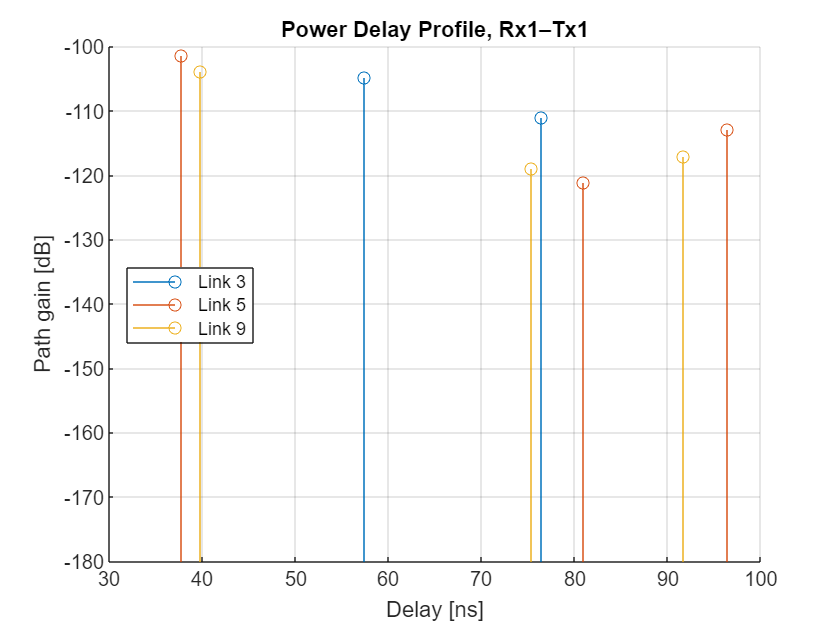

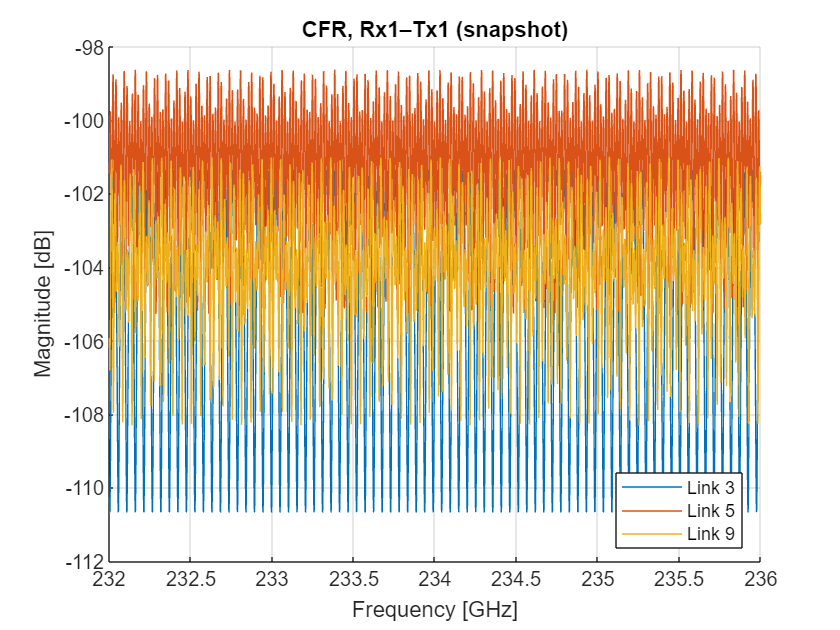

if visualizeChModel
    % Choose which 3 links to visualize (by their indices in par.linkSet)
    % Example: plot link #1, #5, and #9
    plotLinks = [3 5 9];  

    % Safety check in case you ask for links that don’t exist
    plotLinks = plotLinks(plotLinks <= Nlink);

    leg = cell(1, numel(plotLinks));

    % ---- Power Delay Profile (PDP) ----
    figure(10); clf; hold on;
    for idx = 1:numel(plotLinks)
        i_link = plotLinks(idx);
        stem(Delay(i_link,:,1)*1e9, ...
             squeeze(20*log10(abs(CIR(i_link,1,1,:,1))))', ...
             'BaseValue', -180, 'DisplayName', ...
             sprintf('Link %d', par.linkSet(i_link)));
    end
    grid on; hold off;
    xlabel('Delay [ns]');
    ylabel('Path gain [dB]');
    title('Power Delay Profile, Rx1–Tx1');
    legend('show', 'Location','best');

    % ---- Channel Frequency Response (CFR) ----
    figure(11); clf; hold on;
    for idx = 1:numel(plotLinks)
        i_link = plotLinks(idx);
        plot(freq*1e-9, 20*log10(abs(squeeze(CFR(i_link,1,1,:,1)))), ...
            'DisplayName', sprintf('Link %d', par.linkSet(i_link)));
    end
    grid on; hold off;
    xlabel('Frequency [GHz]');
    ylabel('Magnitude [dB]');
    title('CFR, Rx1–Tx1 (snapshot)');
    legend('show', 'Location','best');
end